clear;
num = [30 25];
den = [0.016 0.864 3.27, 3.42 1];
sys = feedback(tf(num, den), 2)

sys =
 
                     30 s + 25
  -----------------------------------------------
  0.016 s^4 + 0.864 s^3 + 3.27 s^2 + 63.42 s + 51
 
Continuous-time transfer function.
Model Properties


[A B C D] = tf2ss([30 25] ,[0.016 0.864 3.27 63.42 51])

A = 1.0e+03 *

   -0.0540   -0.2044   -3.9638   -3.1875
    0.0010         0         0         0
         0    0.0010         0         0
         0         0    0.0010         0


B =      1
     0
     0
     0


C = 1.0e+03 *

         0         0    1.8750    1.5625


D = 0



% eular
r = 20

r = 20

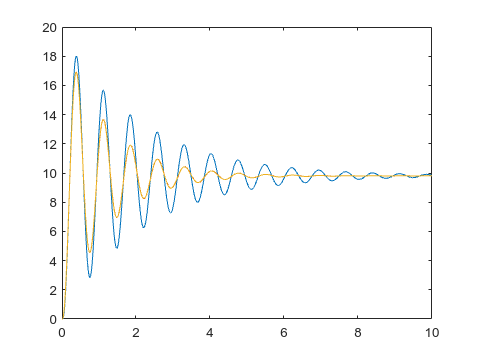

TF = 10; % all time
h = 0.01; % step time
x = [zeros(length(A), 1)]; y = 0; t = 0;

for i = 1 : TF/h
    x = x + h*(A * x + B * r);
    y = [y ; C * x]; 
    t = [t ; t(i) + h];
end
plot(t, y);
hold on;

% rk4
x = [zeros(length(A), 1)]; y = 0; t = 0;

for i = 1 : TF/h
    k1 = A * x + B * r;
    k2 = A * (x + h * k1 / 2) + B * r;
    k3 = A * (x + h * k2 / 2) + B * r;
    k4 = A * (x + h * k3) + B * r;
    x = x + h * (k1 + 2 * k2 + 2 * k3 + k4) / 6;


    y = [y ; C * x]; 
    t = [t ; t(i) + h];
end
plot(t, y);


% ADAMS-2
x = [zeros(length(A), 1)]; y = 0; t = 0;

for i = 1 : TF/h
    x1 = A * x + B * r;
    x0 = x + h * x1;
    x2 = A * x0 + B * r;

    x = x + h/2 * (x1 + x2);

    y = [y ; C * x]; 
    t = [t ; t(i) + h];
end
plot(t, y);
hold off